# Clustering

This example shows how various clustering methods are performed in a well constrcuted toy examples. The simultation study is published in

Moo K. Chung, Camille Garcia Ramos, Felipe Branco De Paiva, Jedidiah, Mathis, Vivek Prabharakaren, Veena A. Nair, Elizabeth Meyerand, Bruce P. Hermann, Jeffery R. Binder, Aaron F. Struck, 2023 Unified Topological Inference for Brain Networks in Temporal Lobe Epilepsy Using the Wasserstein Distance, NeuroImage 15:120436, [https://arxiv.org/pdf/2302.06673.](https://arxiv.org/pdf/2302.06673.)

The exaple codes are modified from the original codes from [https://github.com/laplcebeltrami/dynamicTDA.](https://github.com/laplcebeltrami/dynamicTDA.)

 (C) 2021- Moo K. Chung, Univeristy of Wisconsin-Madison

Update history: 2021 December 22 created; 2022 Otober 24 updated; 2023 March 26 WS_cluster.m added; 2025 january 30 Repackaged for BMI768 class; 2026 Mar 9 Made into mlx. 

## Ground truth for testing false negatives

The simulation generates known topological differences between groups. This provides a reference truth that allows evaluation of the method’s ability to detect true effects and quantify false negatives. The simulation setting for testing false positives are left as an exercise. 

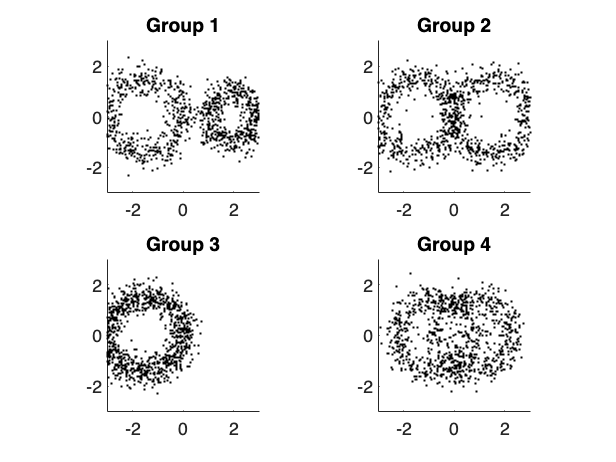

sigma=0.3; %amount of noise
npoints=100; %# of random scatter points along circles

coord=simulate_circle_difference(sigma, npoints); 

%convert scatter points into distance matrices
g= coord2dist(coord);

%nN: number of networks
%NC: number of clusters/groups

[nN nC] = size(coord);
%Visualizing networks
figure;
for j=1:nC
    subplot(2,2,j)
    for i=1:nN
        obs=coord{i,j};
        hold on; plot(obs(:,1), obs(:,2),'.k');
        axis square
        figure_bigger(16)
        xlim([-3 3]); ylim([-3 3]);
        title(['Group ' int2str(j)])
    end
end

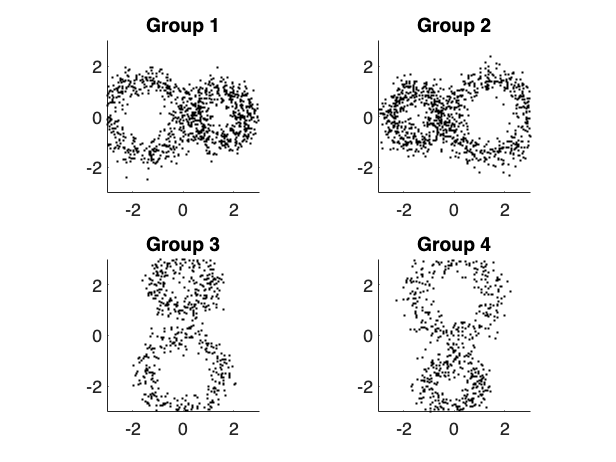

% Random network simulation of no topolgoical difference
coord=simulate_circle_equal(sigma, npoints); 


%convert scatter points into distance matrices
g= coord2dist(coord);

%nN: number of networks
%NC: number of clusters/groups

[nN nC] = size(coord);
%Visualizing networks
figure;
for j=1:nC
    subplot(2,2,j)
    for i=1:nN
        obs=coord{i,j};
        hold on; plot(obs(:,1), obs(:,2),'.k');
        axis square
        figure_bigger(16)
        xlim([-3 3]); ylim([-3 3]);
        title(['Group ' int2str(j)])
    end
end

## Clustering 

Each distance is explained in detail in the above reference [Chung et al. (2023)](https://arxiv.org/pdf/2302.06673.).

% Initilize the clustering accuray. 
acc_K =[];  % k-means - Euclidean distance
acc_B0=[];  % bottleneck-0 distance between graph filtrations
acc_B1=[];  % bottleneck-1 distance between graph filtrations
acc_H = []; % Hierarchical clustering - Gromov-Hausdorff distance
acc_WS =[]; % Wasserstein distance - topoloigcal distance introduced in Chung et al. (2023).

for i=1:5  % May need at least 100 simulations for publication
    
    %generate random scatter points
    %Equal topology
    %coord=simulate_circle_equal(sigma, npoints);
    %Unequal topology
    coord=simulate_circle_difference(sigma, npoints); 

    %convert scatter points into distance matrices
    g= coord2dist(coord);

    %perform clustering
    %k-means 
    acc = kmeans_cluster(g);
    acc_K = [acc_K acc.mean];
    
    %bottleneck distance
    acc = WS_bottleneck_cluster(g);
    acc_B0 = [acc_B0 acc.zero];
    acc_B1 = [acc_B1 acc.one];

    %Hierarchical clustering
    acc = GH_cluster(g);
    acc_H = [acc_H acc];

    %Wasserstein distance
    acc  = WS_cluster(g);
    acc_WS=[acc_WS acc.mean];

end

% Performance metrics
[mean(acc_K) std(acc_K)]

ans =     0.8321    0.0228


[mean(acc_B0) std(acc_B0)]

ans =     0.8500    0.1275


[mean(acc_B1) std(acc_B1)]

ans =     0.8700    0.1151


[mean(acc_H) std(acc_H)]

ans =      1     0


[mean(acc_WS) std(acc_WS)]

ans =     0.9702    0.0132


## Pairwise distance matrix

In this example, the Wasserstein distance does not show a clear clustering pattern because the samples are topologically equivalent. In contrast, the L2-distance shows apparent clustering. Consequently, k-means clustering based on the L2-distance may produce misleading group separation and report many false positives.

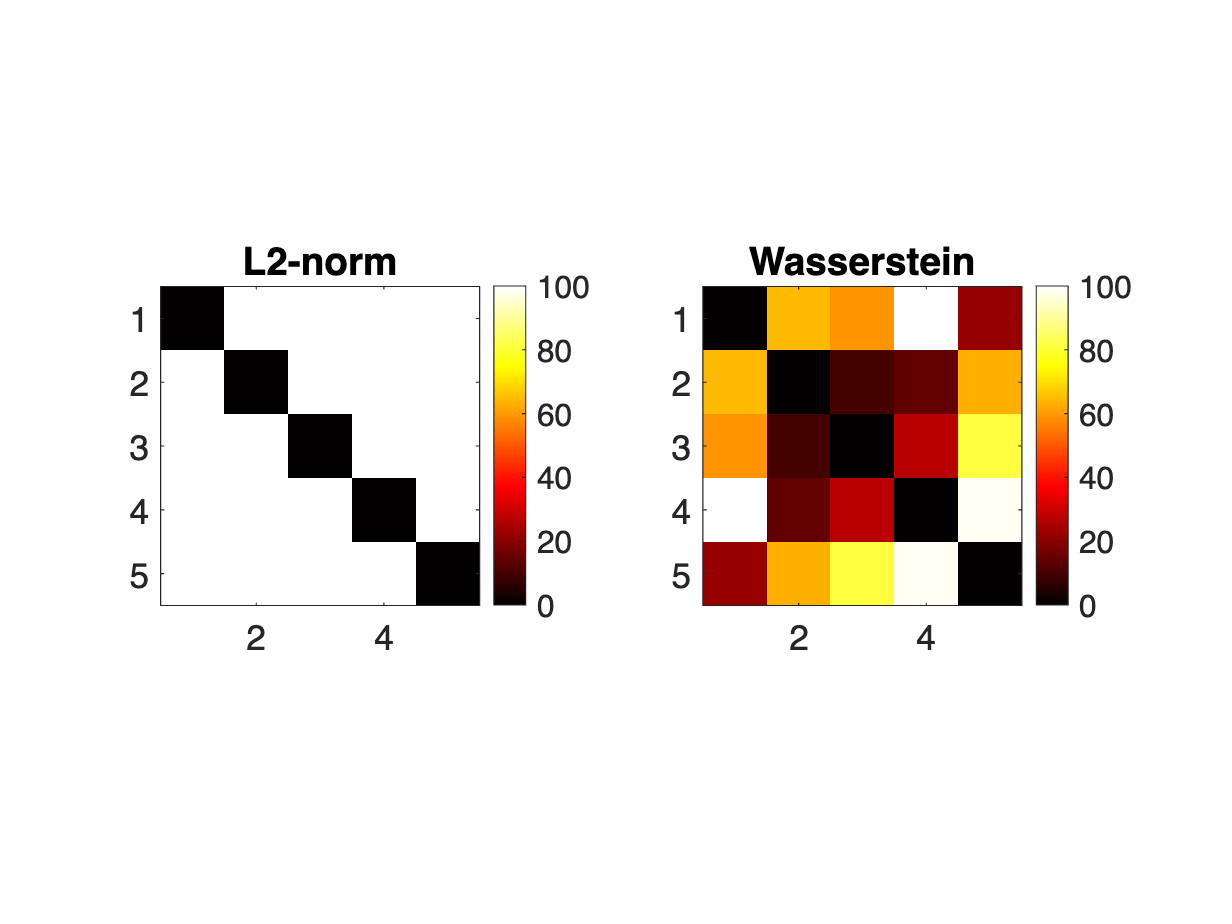

figure; 
subplot(1,2,1)
lossMtx = WS_L2distace2matrix(g);
imagesc(lossMtx); colorbar
axis square
figure_bigger(16)
colormap('hot'); caxis([0 100])
title('L2-norm')

subplot(1,2,2)
lossMtx = WS_distace2matrix(g);
imagesc(lossMtx); colorbar
axis square
figure_bigger(16)
colormap('hot'); caxis([0 100])
title('Wasserstein')